#### Load the datasets

load('IQDataSetTrainingMod.mat')
load('IQDataSetTestMod.mat')
load('IQLabelTestMod.mat')
labels = DataRateAveTraining';
testLabels = DataRateAveTest';

#### Rearrange training dataset

% Parameters
data = cell(800,1);
tempMatrix = zeros(64,1000);
n = 1;

for row = 1:800
    for iteration = 1:64
        tempMatrix(iteration,:) = DataSetPureTraining(row,n:n+999);
        n = n + 1000;
    end
    n = 1;
    data{row} = tempMatrix;
end

#### Rearrange testing dataset

% Parameters
testData = cell(200,1);
tempMatrix = zeros(64,1000);
n = 1;

for row = 1:200
    for iteration = 1:64
        tempMatrix(iteration,:) = DataSetPureTest(row,n:n+999);
        n = n + 1000;
    end
    n = 1;
    testData{row} = tempMatrix;
end

#### Prepeare some parameters and divide the datasets

numSignals = numel(data)

numSignals = 800

numFrames = size(data{1},1)

numFrames = 64

numResponses = size(labels,2)

numResponses = 1

% plot(data{1}(:,:))
rng(30);
[idxTrain,idxValidation] = trainingPartitions(numSignals, [0.8 0.2]);

XTrain = data(idxTrain);
XValidation = data(idxValidation);
XTest = testData;

TTrain = labels(idxTrain);
TValidation = labels(idxValidation);
TTest = testLabels;

#### Implementation of the DNN

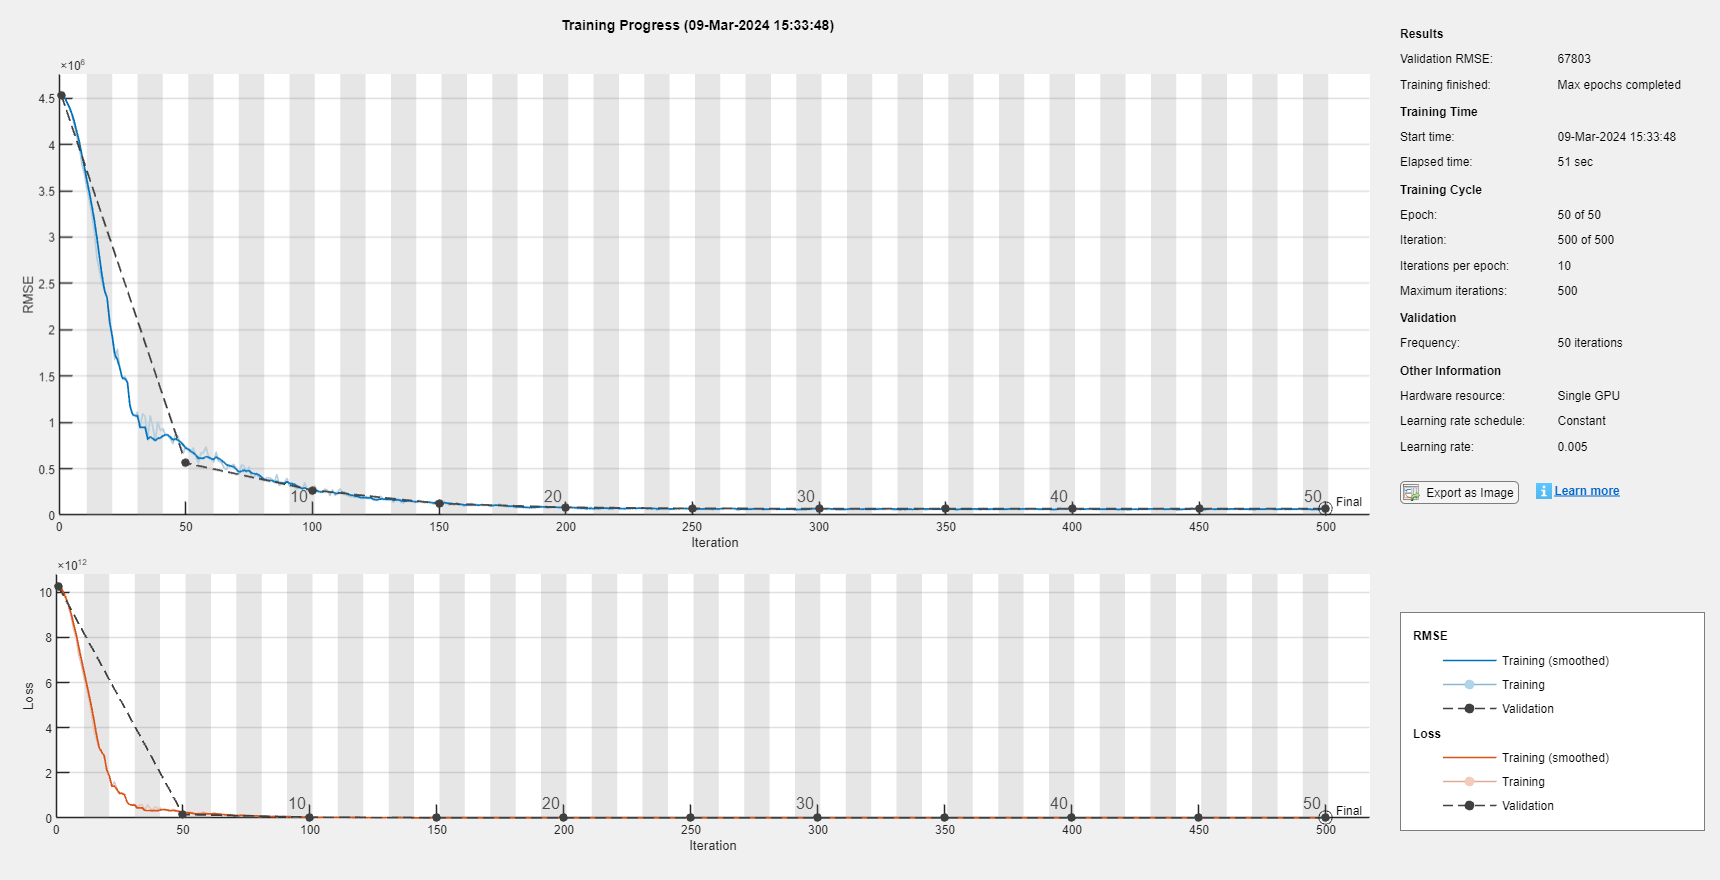

numHiddenUnits = 128;

layers = [
    sequenceInputLayer(64,"Name","sequence","SplitComplexInputs",true,'Normalization', 'zerocenter')
    lstmLayer(numHiddenUnits,"Name","lstm","OutputMode","last")
    dropoutLayer(0.5, "Name", "dropout")
    fullyConnectedLayer(1,"Name","fc")
    regressionLayer("Name","regressionoutput")];

options = trainingOptions("sgdm", ...
    MaxEpochs=50, ...
    MiniBatchSize= 64,...
    ValidationData={XValidation TValidation}, ...
    OutputNetwork="best-validation-loss", ...
    Shuffle="every-epoch",...
    InitialLearnRate=0.005, ...
    Plots="training-progress", ...
    Verbose= false);

net = trainNetwork(XTrain, TTrain, layers, options);

#### Predicting data-rates using the DNN

YTest = predict(net,XTest, SequenceLength="shortest");
rmse = sqrt(mean((YTest-TTest).^2))

rmse = single
6.5807e+04

#### Actual vs Predicted

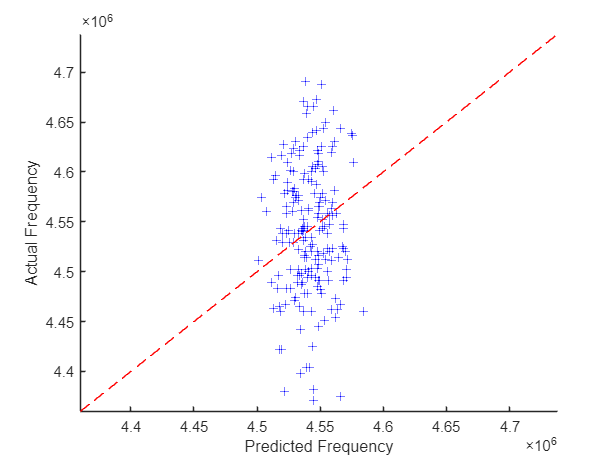

figure
scatter(YTest,TTest, "b+");
xlabel("Predicted Data-rate")
ylabel("Actual Data-rate")
hold on

m = min(labels);
M=max(labels);
xlim([m M])
ylim([m M])
plot([m M], [m M], "r--")